# Covid transmission with inactivation measures

clearvars; clc;

#### Define parameters

eps = .7421;
% Yang's inactivation time yields eps = .7421
% The Columbia university study with UVC gives eps = .6596 
beta = 0.5;

## Half intervention

tspan = 0:500;
N = 328.2e6;
% half intervention
y0 = [N/2-35,25,10,0,0,0,0,N/2-35,25,10,0,0,0,0];

[t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);

y_sum_half = [(y(:,1)+y(:,8)) (y(:,2)+y(:,9)) (y(:,3)+y(:,10)) (y(:,4)+y(:,11)) (y(:,5)+y(:,12)) (y(:,6)+y(:,13)) (y(:,7)+y(:,14))];
num_infec_half = y(:,3) + y(:,10);
num_deaths_half = y(:,7) + y(:,14);
pred_cases_half = y(:,3) + y(:,5) + y(:,6) + y(:,7) + ...
            y(:,10) + y(:,12) + y(:,13) + y(:,14);
% no intervention
y0 = [N-70,50,20,0,0,0,0,0,0,0,0,0,0,0];
[t,y]= ode45(@(t,y)ode_radiation(t,y,eps, beta),tspan,y0);

y_sum_no_int = [(y(:,1)+y(:,8)) (y(:,2)+y(:,9)) (y(:,3)+y(:,10)) (y(:,4)+y(:,11)) (y(:,5)+y(:,12)) (y(:,6)+y(:,13)) (y(:,7)+y(:,14))];

pred_cases_no_int = y(:,3) + y(:,5) + y(:,6) + y(:,7) + ...
            y(:,10) + y(:,12) + y(:,13) + y(:,14);
num_infec_no_int = y(:,3) + y(:,10);
num_deaths_no_int = y(:,7) + y(:,14);


#### Plot results

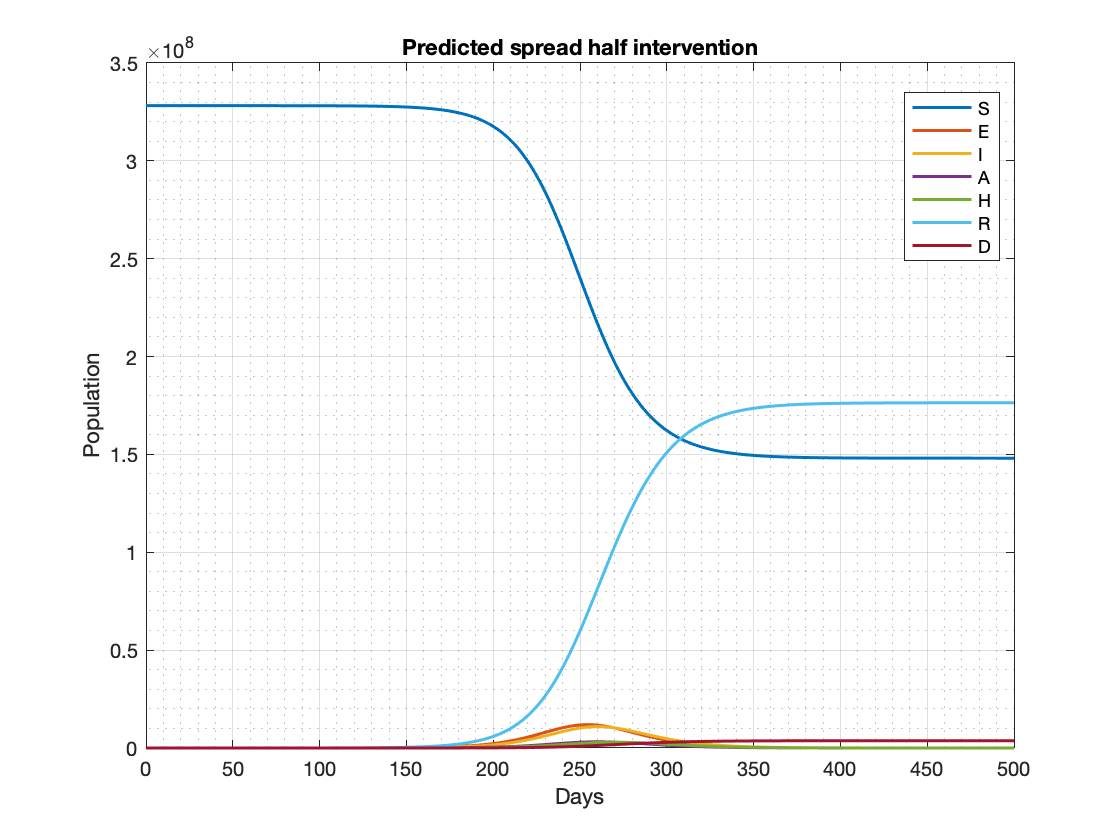

plot(t,y_sum_half,'LineWidth',1.5,'MarkerSize',18);
legend('S','E','I','A','H','R','D','Location','best')
xlabel('Days')
ylabel('Population')
title('Predicted spread half intervention')
grid on;
grid minor;

hold off;

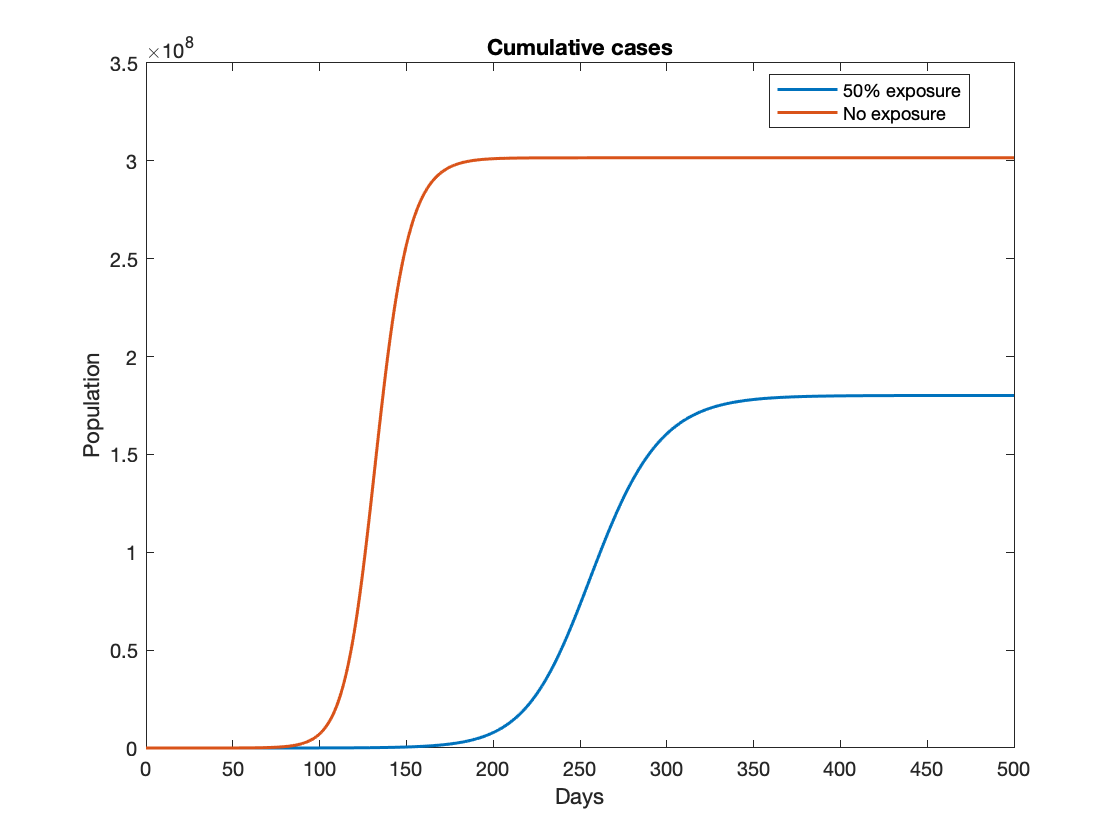


figure
plot(t,pred_cases_half,'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(t,pred_cases_no_int, 'LineWidth', 1.5, 'MarkerSize', 18);
xlabel('Days')
ylabel('Population')
title('Cumulative cases')
legend('50% exposure','No exposure','Location','best');
hold off

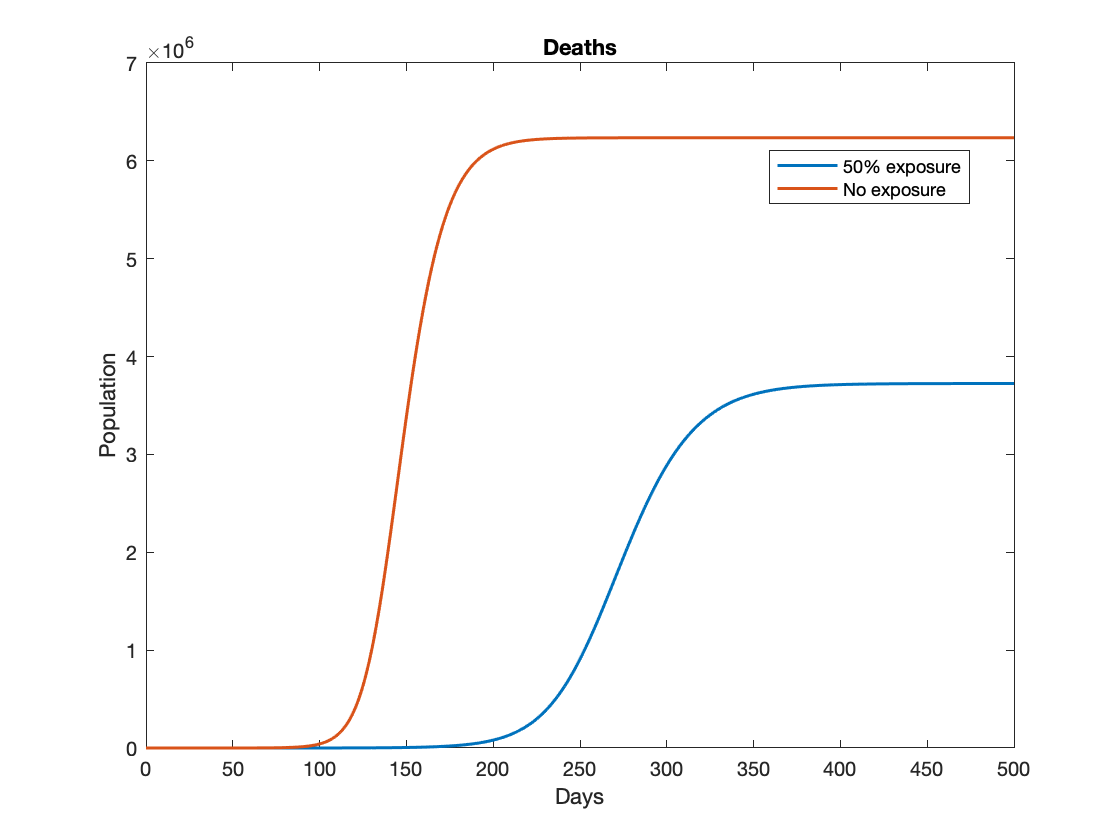


figure
plot(t,num_deaths_half,'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(t,num_deaths_no_int, 'LineWidth', 1.5, 'MarkerSize', 18);
xlabel('Days')
ylabel('Population')
title('Deaths')
legend('50% exposure','No exposure','Location','best');
hold off

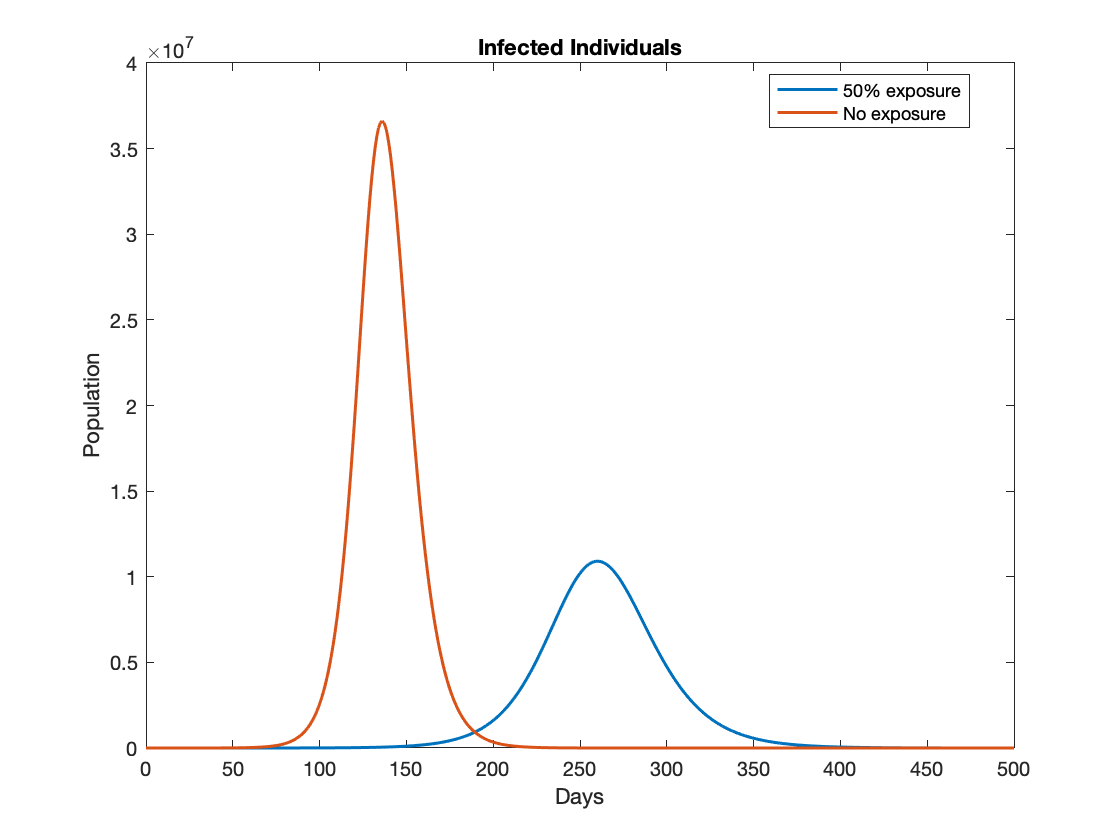


figure
plot(t,num_infec_half,'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(t,num_infec_no_int, 'LineWidth', 1.5, 'MarkerSize', 18);
xlabel('Days')
ylabel('Population')
title('Infected Individuals')
legend('50% exposure','No exposure','Location','best');
hold off

## By percent intervention

peakhospitalnum = zeros(101,1);
peakhospitalday = zeros(101,1);

totaldeaths = zeros(101,1);

for percent_rad = 0:100
    tspan = 0:1:500;
    y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];

    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp = y(:,5) + y(:,12);
    [peakhospitalnum(percent_rad+1),peakhospitalday(percent_rad+1)]=max(hosp);
    
    deaths(percent_rad + 1) = y(end,7) + y(end,14);
end


#### Plot results

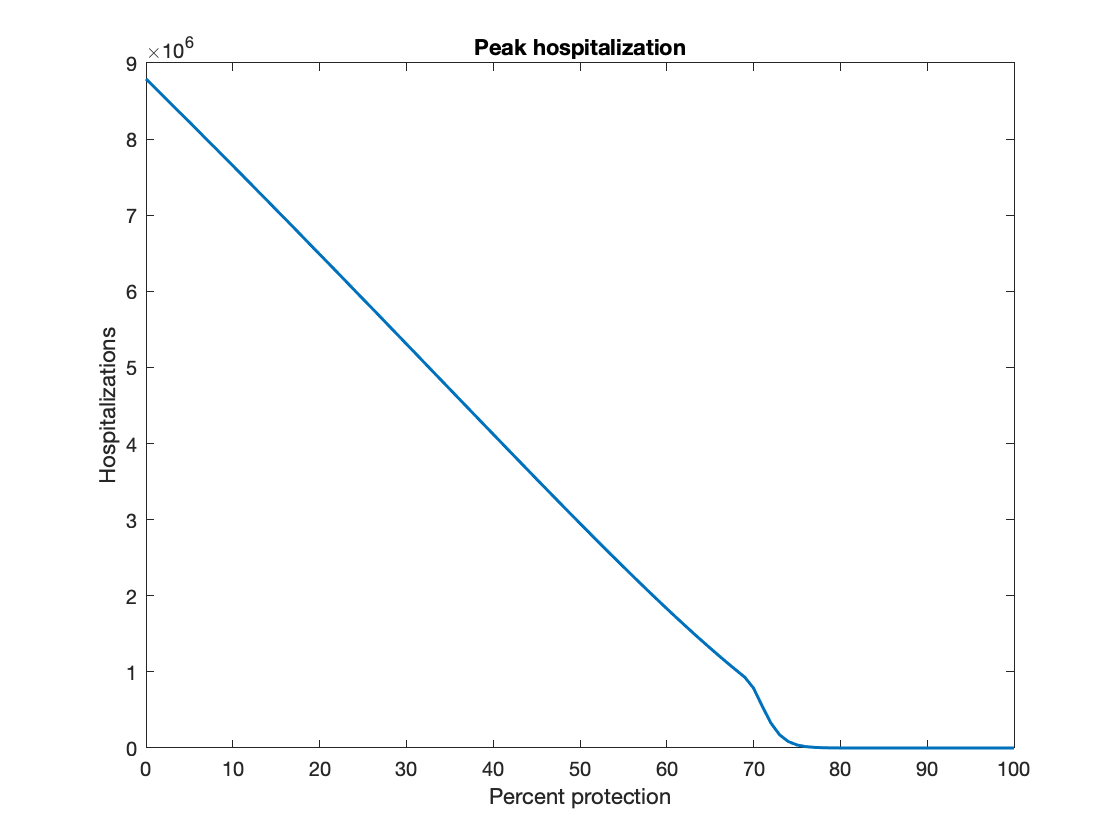

figure
plot(0:100, peakhospitalnum, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent protection')
ylabel('Hospitalizations')
title('Peak hospitalization')
hold off;

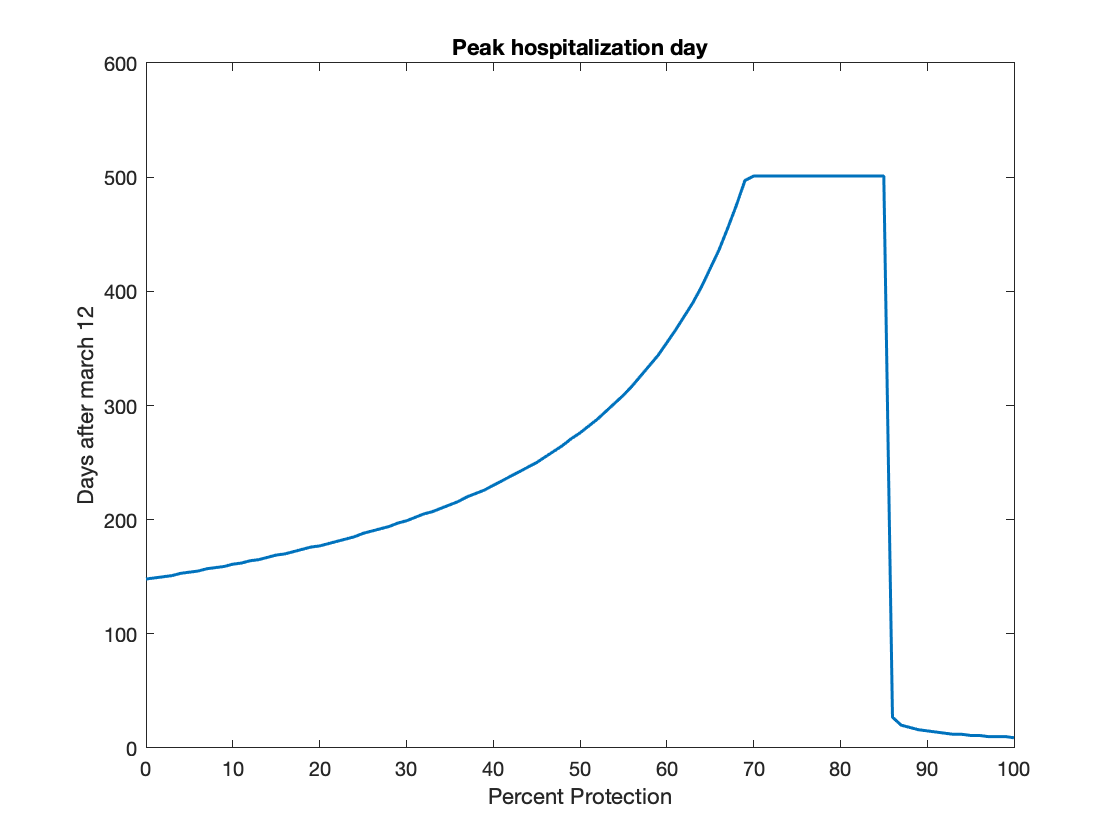


figure
plot(0:100, peakhospitalday, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent Protection')
ylabel('Days after march 12')
title('Peak hospitalization day')
hold off;

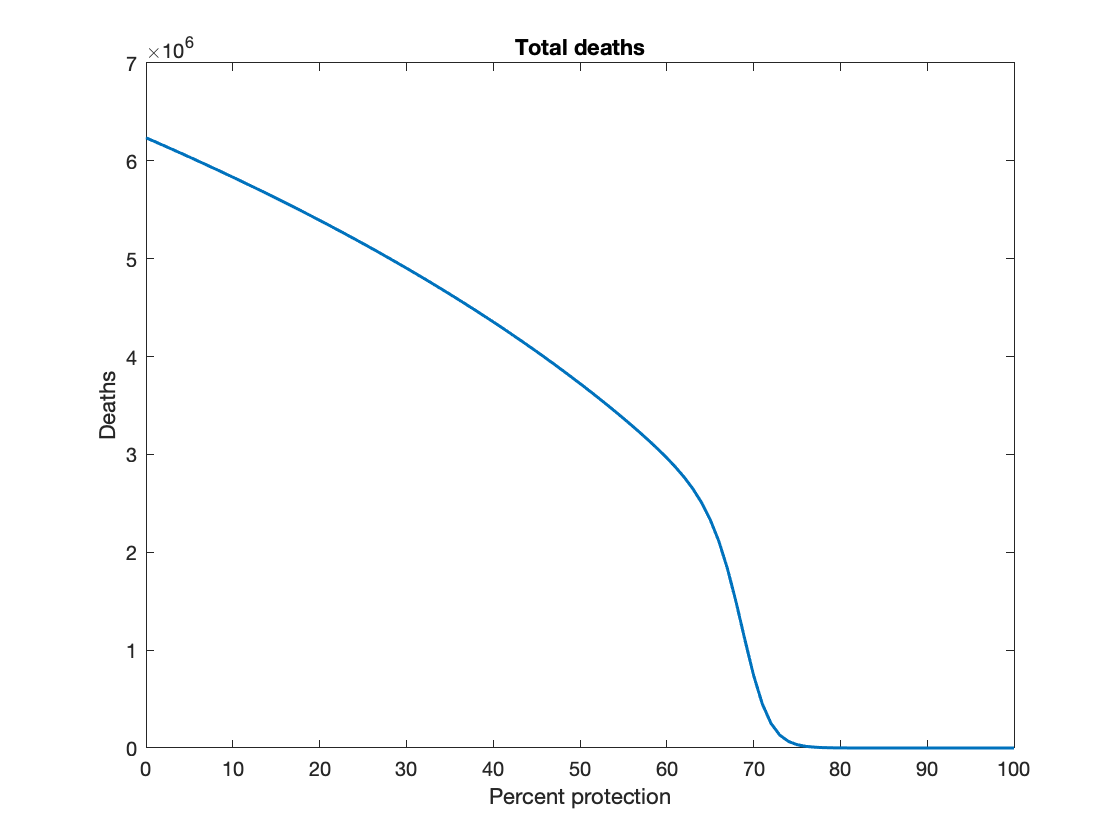


figure
plot(0:100, deaths, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent protection')
ylabel('Deaths')
title('Total deaths')
hold off;

## Plot peak hospitalizations

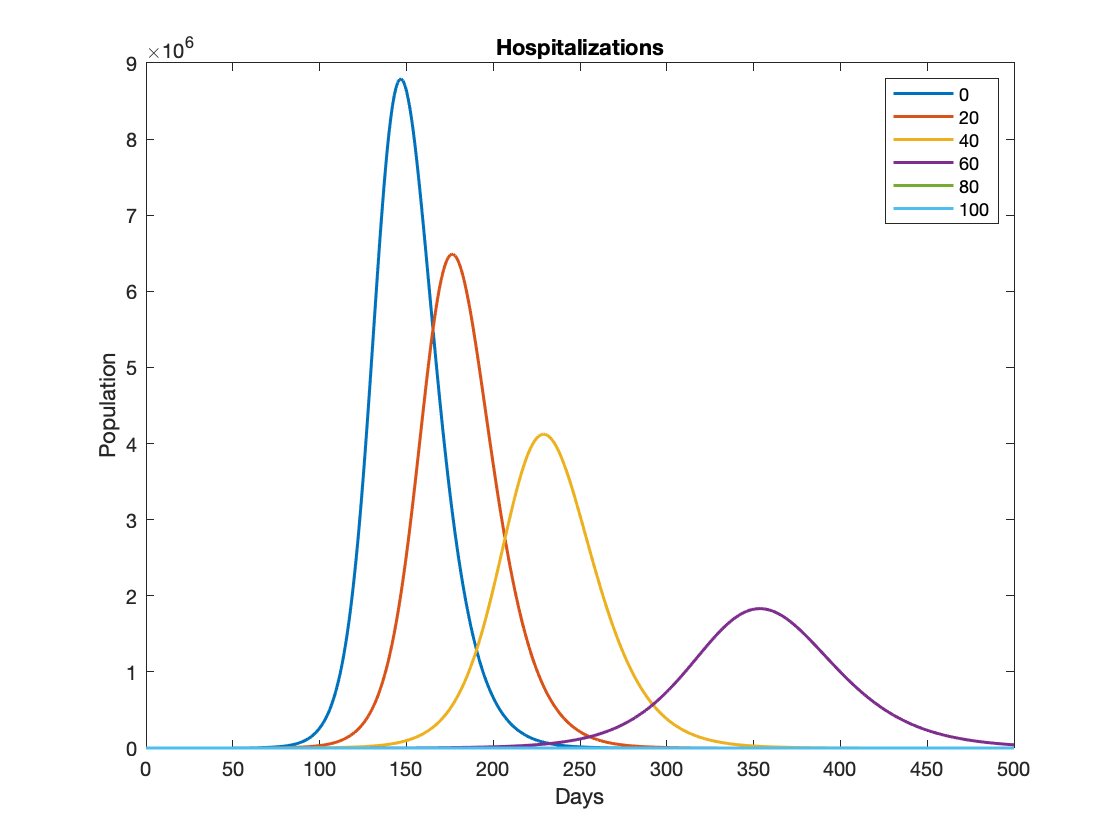

hosp = zeros(501,6);

for iter = 1:6
    percent_rad = (iter-1)*20;
    
    y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];

    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp(:,iter) = y(:,5) + y(:,12);
end

figure
plot(0:500, hosp, 'LineWidth', 1.5,  'MarkerSize', 18);
legend('0','20', '40','60','80','100')
xlabel('Days')
ylabel('Population')
title('Hospitalizations')

## Impact of varying time of inactivation

The base area under the curve is 112.846

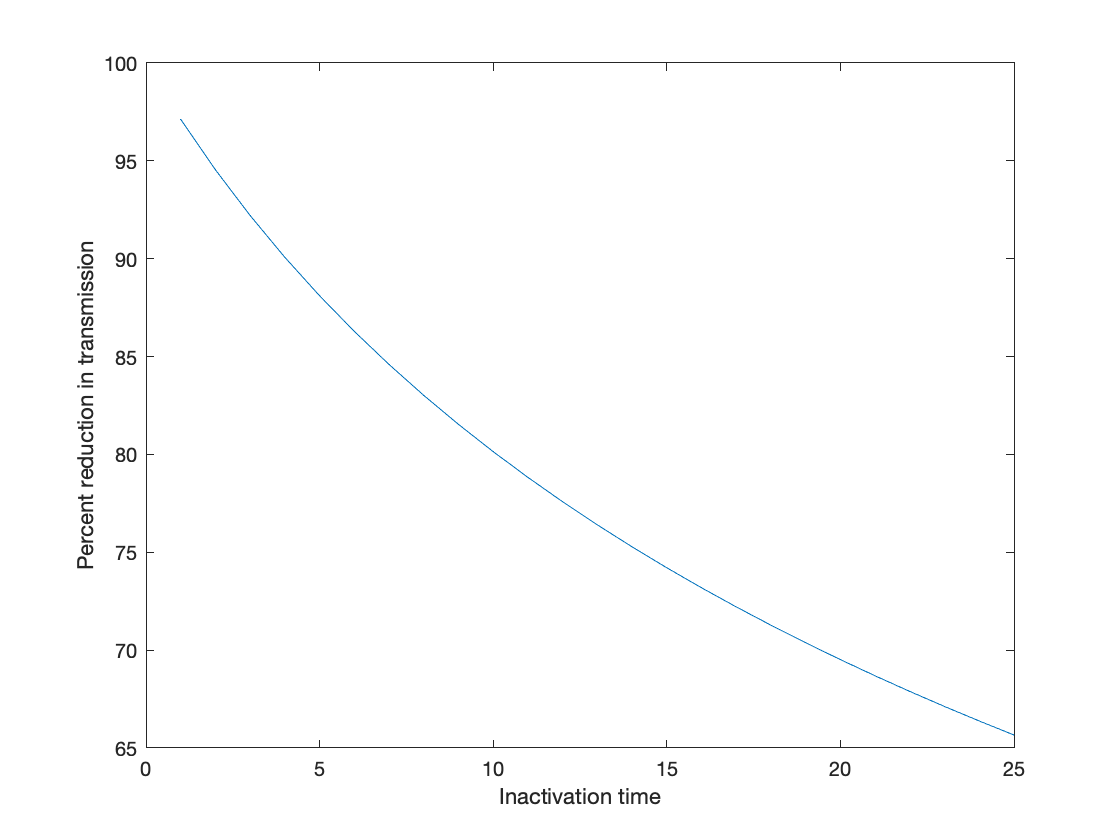

deaths_matrix = zeros(101,25);
peakhospitalnums_matrix = zeros(101,25);
peakhospitaldays_matrix = zeros(101,25);

for percent_rad = 0:100
    
    
    for inactivation_time = 1:25
        tspan = 0:1:365;
        y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];
        
        root = 1000/61*lambertw(61*inactivation_time/1000);
        fun = @(x) 6.8836*exp(-.061*x)-6.8836*x/inactivation_time;
        area = integral(fun,0,root);
        eps = (112.846-area)/112.846;
        
            [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp = y(:,5) + y(:,12);
    [peakhospitalnums,peakhospitaldays]=max(hosp);
    peakhospitalnums_matrix(percent_rad+1, inactivation_time) = peakhospitalnums;
    peakhospitaldays_matrix(percent_rad+1, inactivation_time) = peakhospitaldays;
    
    deaths = y(366,7) + y(366,14);
    deaths_matrix(percent_rad+1, inactivation_time) = deaths;
    
    end
    

end

eps_vector = zeros(25,1);

for inactivation_time = 1:25
   root = 1000/61*lambertw(61*inactivation_time/1000);
        fun = @(x) 6.8836*exp(-.061*x)-6.8836*x/inactivation_time;
        area = integral(fun,0,root);
        eps_vector(inactivation_time,1) = (112.846-area)/112.846;
end
eps_vector = eps_vector*100;

%Plot data
figure
plot(eps_vector)
xlabel('Inactivation time');
ylabel('Percent reduction in transmission')

grid off; 
colormap jet;

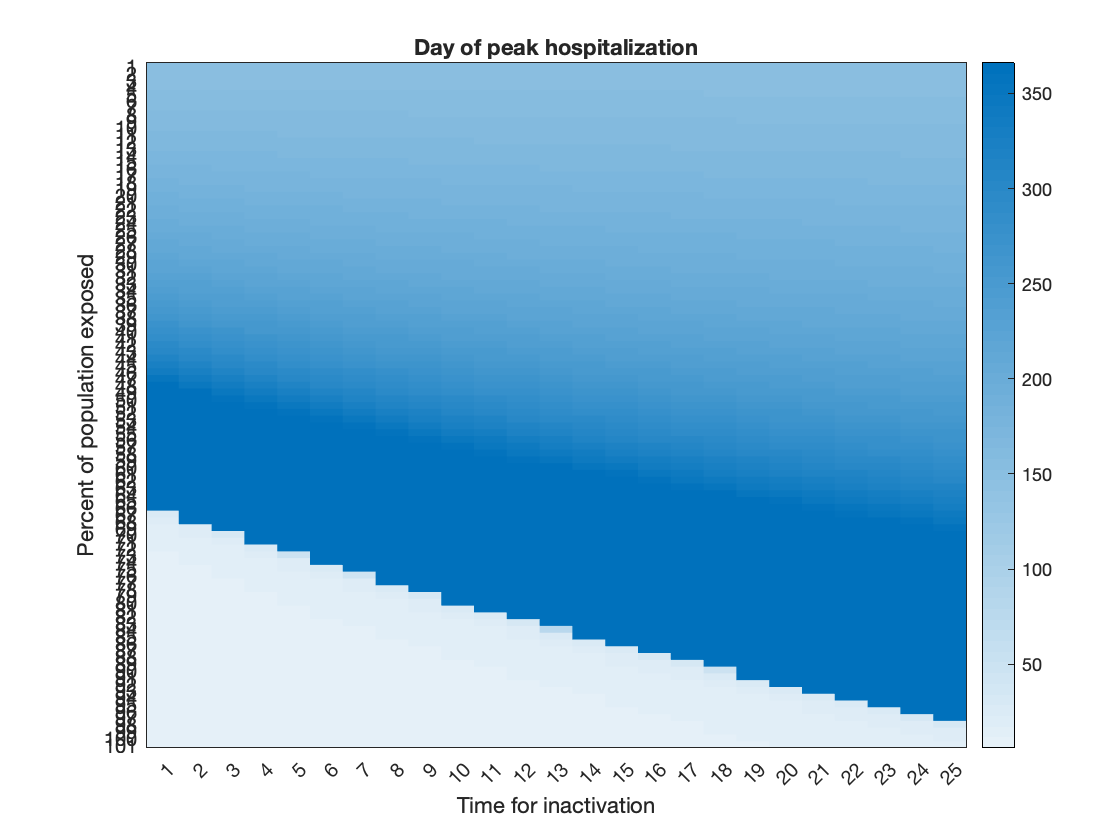


figure
heatmap(peakhospitaldays_matrix,'CellLabelColor','none','GridVisible',"off")
title( ...
    'Day of peak hospitalization')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")

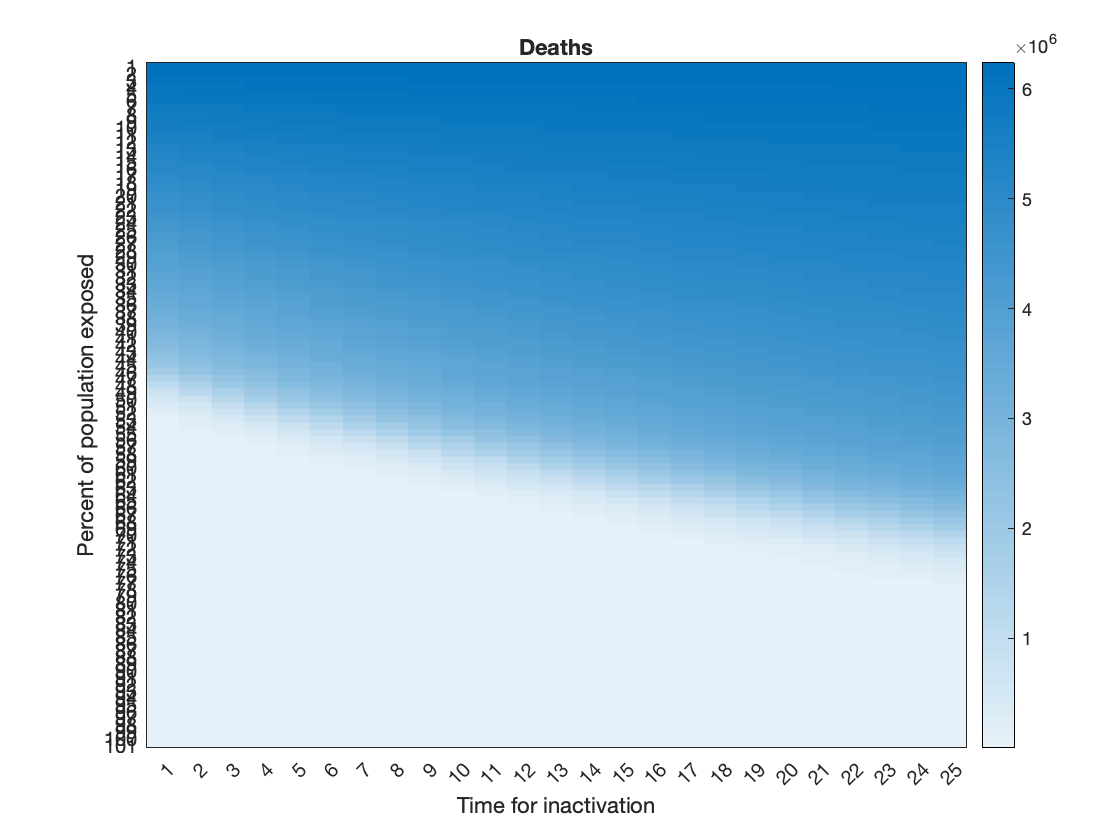


figure
grid off; 
colormap jet;
heatmap(deaths_matrix,'CellLabelColor','none','GridVisible',"off")
title('Deaths')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")

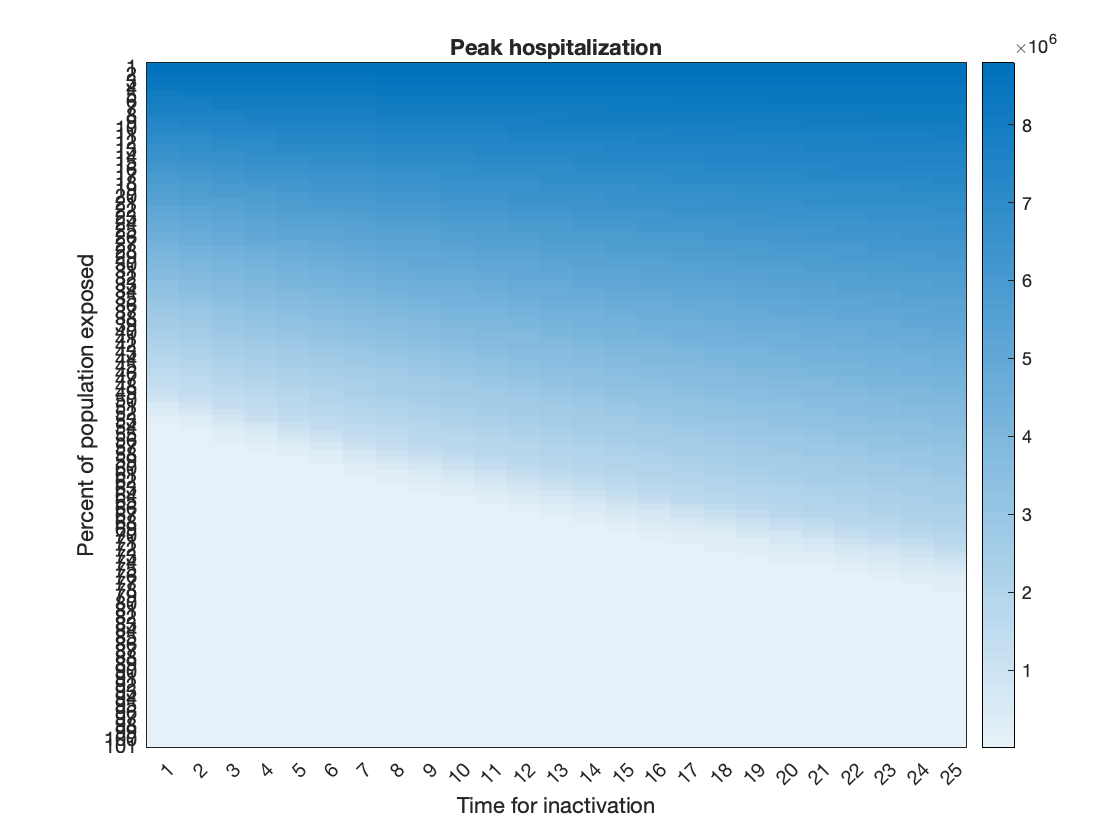


figure
grid off; 
colormap jet;
heatmap(peakhospitalnums_matrix,'CellLabelColor','none','GridVisible',"off")
title('Peak hospitalization')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")

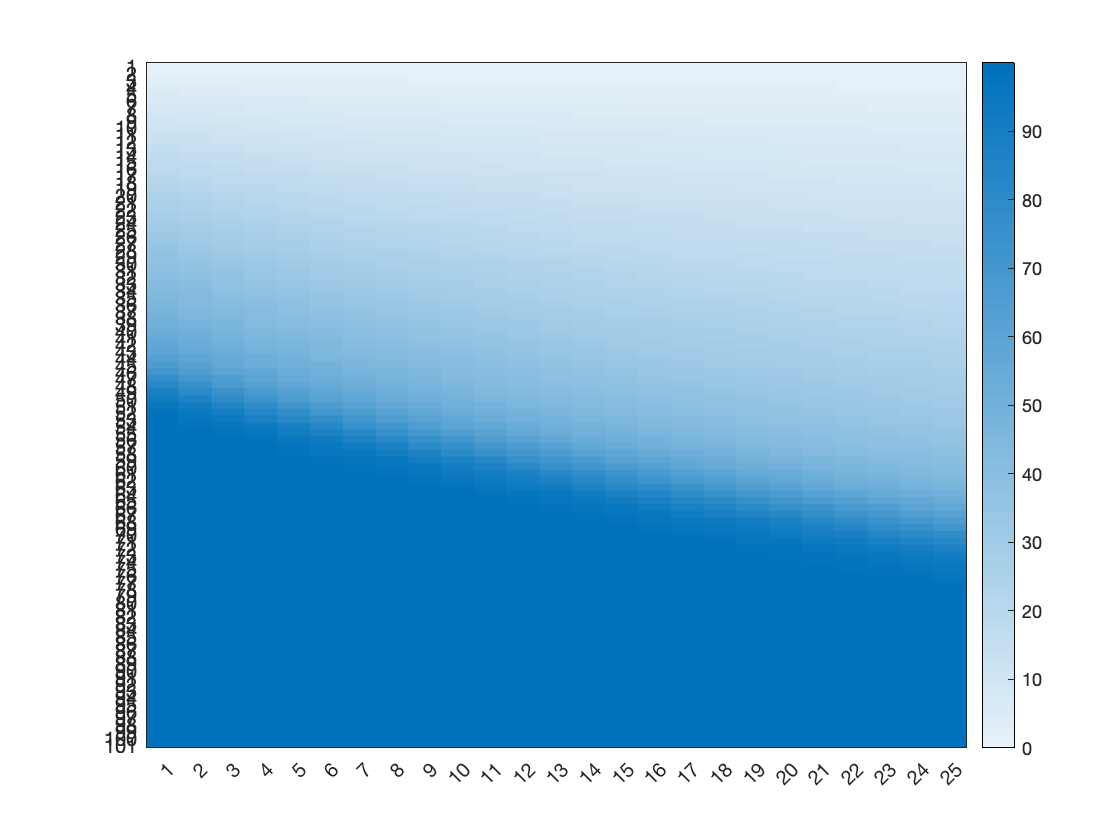


percent_red_deaths_matrix = (1-deaths_matrix./(max(max(deaths_matrix))))*100;
heatmap(percent_red_deaths_matrix, 'CellLabelColor','none','GridVisible',"off") 

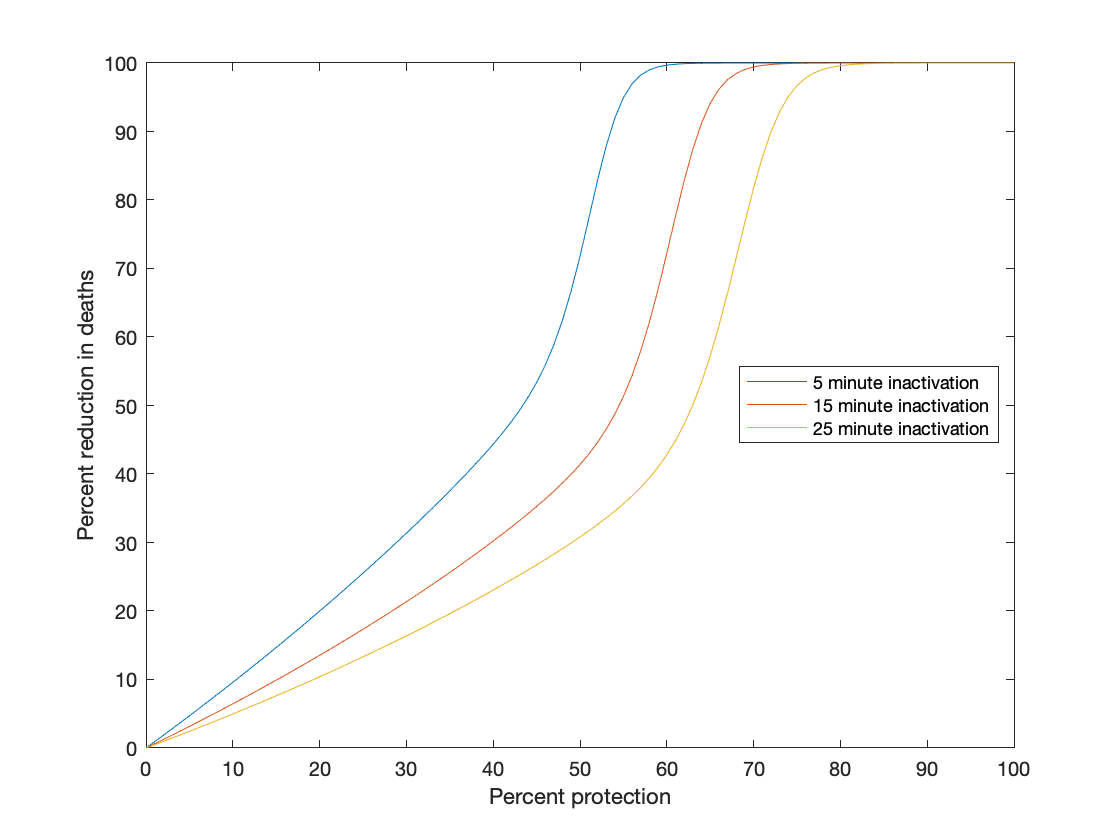


figure
plot(0:100,percent_red_deaths_matrix(:,5))
hold on
plot(0:100,percent_red_deaths_matrix(:,15))
hold on
plot(0:100,percent_red_deaths_matrix(:,25))
 legend('5 minute inactivation','15 minute inactivation','25 minute inactivation', 'Location','Best')
xlabel('Percent protection')
ylabel('Percent reduction in deaths')
hold off

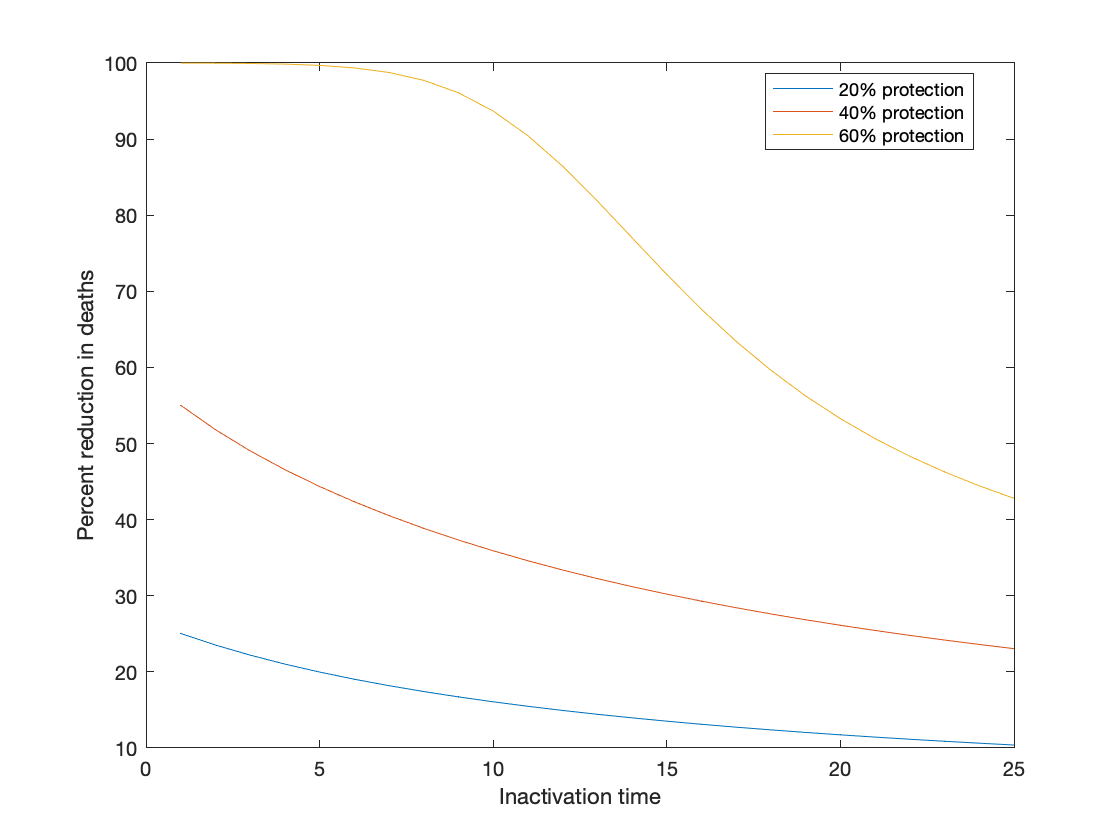


figure
plot(1:25, percent_red_deaths_matrix(21,:));
hold on;
plot(1:25, percent_red_deaths_matrix(41,:));
hold on;
plot(1:25, percent_red_deaths_matrix(61,:));


xlabel('Inactivation time');
ylabel('Percent reduction in deaths')
legend('20% protection', '40% protection', '60% protection', 'Location','best');

function dydt = ode_radiation(t,y,eps, beta)

%gotta define the constants in here
%beta = 0.1986
N = 328.2e6;

pre_infec = 5.1;
sigma = 1/pre_infec;
eta = 0.5;
alpha = 0.8;
phi = 0.025;
gamma_A = 1/7;
gamma_I = 1/7;
gamma_H = 1/14;
delta = 0.015;


S = y(1);
E = y(2);
I = y(3);
A = y(4);
H = y(5);
R = y(6);
D = y(7);
S_R = y(8);
E_R = y(9);
I_R = y(10);
A_R = y(11);
H_R = y(12);
R_R = y(13);
D_R = y(14);

dS = -beta.*(I+eta.*A).*S./N - beta.*((1-0).*I_R+(1-0).*eta.*A_R).*S./N;
dE = beta.*(I+eta.*A).*S./N + beta.*((1-0)*I_R + (1-0)*eta*A_R).*S/N- sigma.*E;
dI = alpha.*sigma.*E-phi.*I-gamma_I.*I;
dA = (1-alpha).*sigma.*E-gamma_A.*A;
dH = phi.*I-delta.*H-gamma_H*H;
dR = gamma_I*I+gamma_A*A + gamma_H*H;
dD = delta*H;

dS_R = -beta.*(1-eps)*(I+eta*A).*S_R./N-beta.*(1-eps)*((1-0).*I_R + (1-0)*eta.*A_R)*S_R/N;
dE_R = beta.*(1-eps)*(I+eta*A).*S_R./N + beta.*(1-eps)*((1-0)*I_R+(1-0)*eta*A_R).*S_R./N - sigma.*E_R;
dI_R = alpha.*sigma.*E_R-phi.*I_R-gamma_I.*I_R;
dA_R = (1-alpha).*sigma.*E_R-gamma_A.*A_R;
dH_R = phi.*I_R-delta.*H_R-gamma_H*H_R;
dR_R = gamma_I*I_R+gamma_A*A_R + gamma_H*H_R;
dD_R = delta*H_R;

dydt = [dS;dE;dI;dA;dH;dR;dD;dS_R;dE_R;dI_R;dA_R;dH_R;dR_R;dD_R];
end